## Basic demonstration of fmincon

See Q4 on the lab 03 worksheet.

We are asked to study the objective function


$$F(x,y)=\lambda(\sin{x}+\sin{y})-x-2y$$


for $x,y\geq0$, with $\lambda>0$ a parameter we play with, setting eg $\lambda=3$ initially.

### Set up of anonymous function

lambda=3

lambda = 3

funEddieV1 = @(x,y)(lambda*(sin(x)+sin(y))-x-2*y)

funEddieV1 = function_handle with value:
    @(x,y)(lambda*(sin(x)+sin(y))-x-2*y)


funEddieV1 is now a function handle which defines the V1 (first version of the) function we want to explore - in fact, it will need a bit more 'packaging' before passing to fmincon, but what fmincon will ultimately do is explore this function by calling it many many times to find a (local) minimum. 

### Setting up data for plotting

First, set up a lower and upper bound for $x$ and $y$ for the plot and the number of grid points in each direction.

npts=1000

npts = 1000

lb=0

lb = 0

ub=40

ub = 40

Then set up vectors x and y whicih are essentially the 'tick values' on each of the axes, and set up matrices X and Y which contain all the combinations of grid points on the mesh. If you don't get this - try looking at X, Y directly for a small value of npts, say 5.

x=linspace(lb,ub,npts);
y=linspace(lb,ub,npts);
[X,Y]=meshgrid(x,y);

NB, be very careful - each of these structures X and Y takes 8*npts*npts bytes, and things go out of memory very quickly, as they did in my lecture.

Now funEddieV1, as written, will if passed vectors or matrices of arguments, compute the given function component-wise at each of the elements and return a vector or matrix of values. We can thus compute all of the F data in one command as follows. 

Z=funEddieV1(X,Y);

Other functions, which eg involved x*y in their computation, would need a .* syntax to force the correct component-wise computation.

### Plotting the function

Here are some different methods, different commands. Look at the help pages for the various commands shown here and experiment with the options.

Surface plot with lighting - notice you can grab and rotate it:

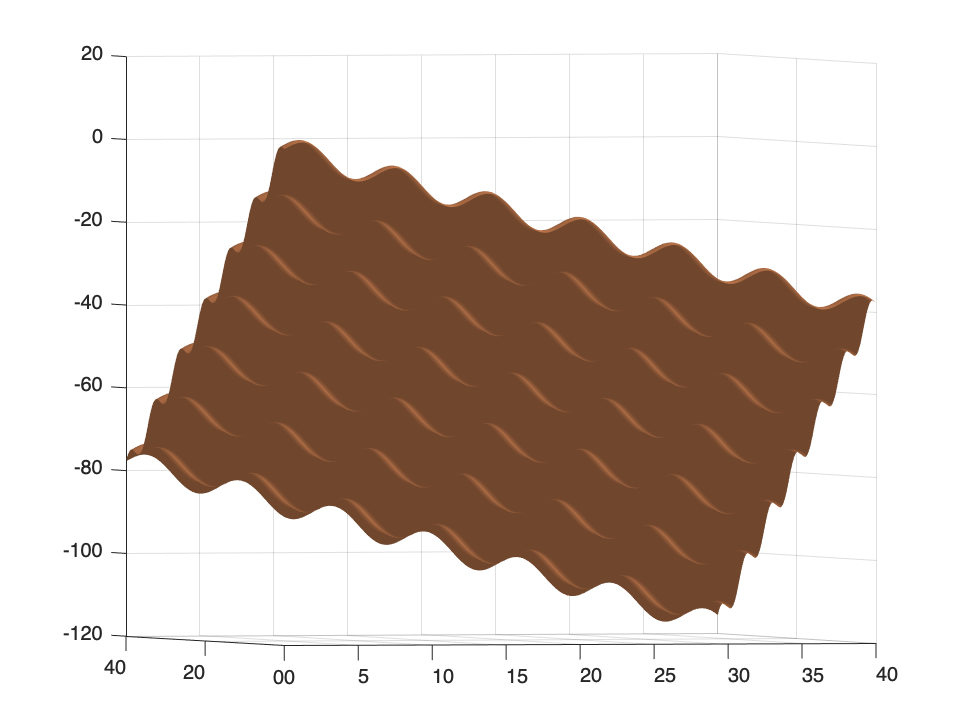

figure;
surfl(X,Y,Z); 
shading flat
colormap copper

Intensity plot - the image and imagesc commands do a similar thing:

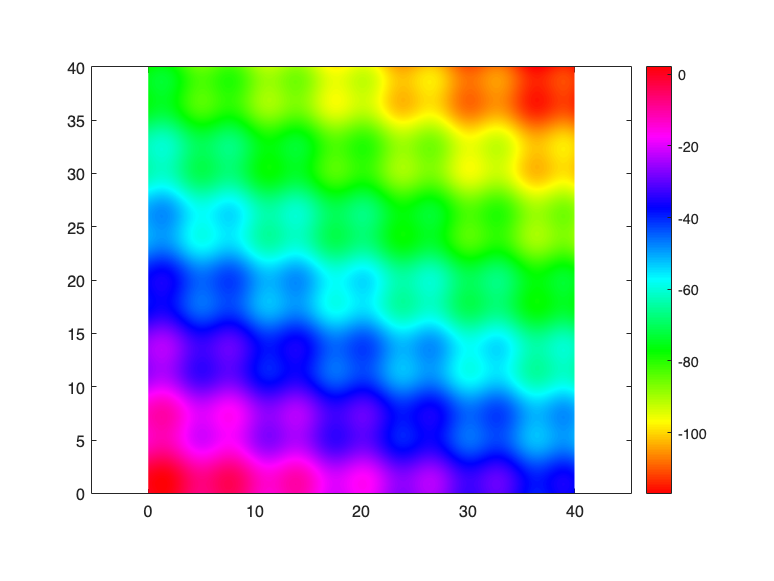

figure;
pcolor(X,Y,Z); 
shading flat; colormap(hsv); axis equal
colorbar

Contour plot - here configured to plot contours at 50 different levels.

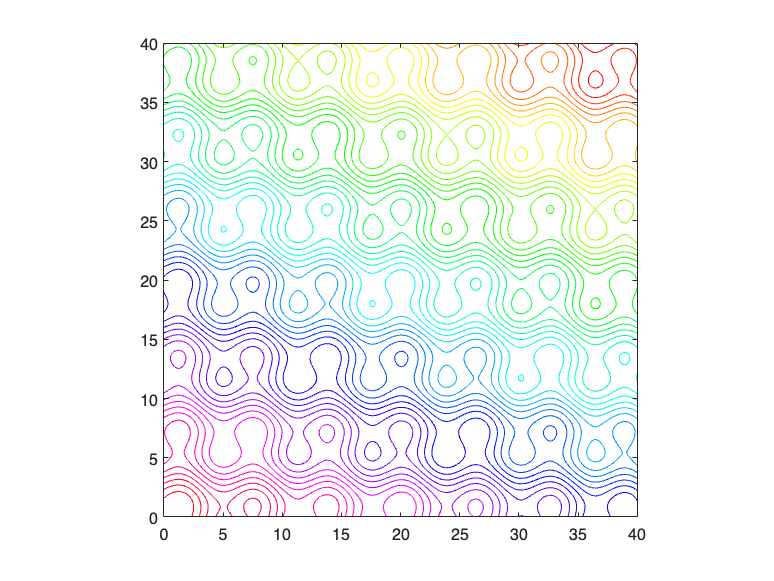

contour(X,Y,Z,50); axis equal
hold on

It should be obvious from each of these plots that (quite deliberately) the function is very bumpy with lots of local minima and maxima. However, there is a sort of large-scale slope so that the global minimum is towards the top right hand corner.  

I've saved a handle to this figure so we can plot some extra info across the top.

### Calling fmincon

If we are going to enforce lower (and maybe upper) bounds for $x$ and $y$, we need to use the long form of the call to fmincon, in the form

Notice, the linear inequality and equality constraints defined by A,B,Aeq, and Beq have the same meaning as in the function linprog, and are empty in this example as presently set. Also there are are no nonlinear constraints, so there is no need to use the longer argument list including nonlcon.

However, before we proceed, we also need to package-up funEddieV1. This is because fmincon wants to call an objective function which takes a single vector-valued argument of all of the decision variables, not one which breaks out the decision variables into individual arguments. This packaging can be achieved like this - where I am now calling the vector that holds x and y values "xy":

funEddieV2 = @(xy)funEddieV1(xy(1),xy(2))

funEddieV2 = function_handle with value:
    @(xy)funEddieV1(xy(1),xy(2))


Note that generally in these problems, one needs to set a starting guess, we'll call it xy0, and that generally, this will influence the local minimum that is subsequently found - as shown below and illustrated on the contour plot above.

xy0 = [5,4]'; % for example
[xy,fval] = fmincon(funEddieV2,xy0,[],[],[],[],[lb;lb],[ub;ub])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xy =     5.0522
   11.7253


fval = -33.5673

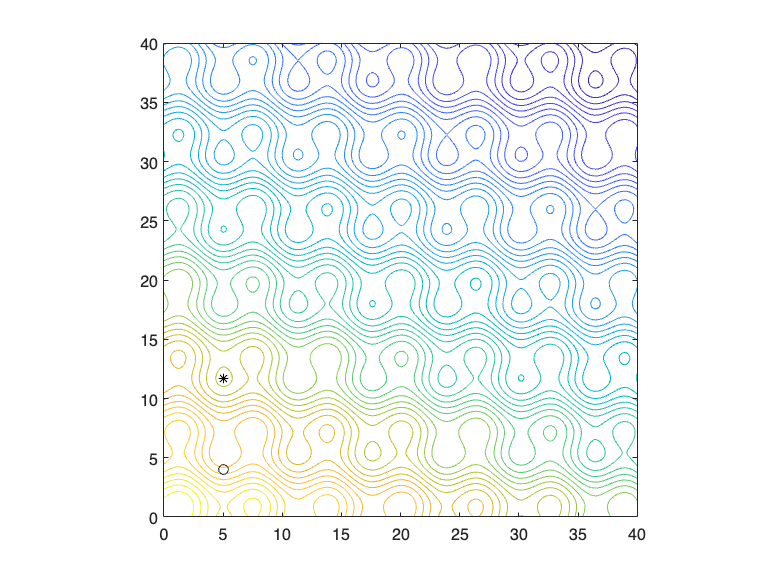

figure;
contour(X,Y,Z,50); axis equal
hold on
plot(xy0(1),xy0(2),'ko') % display starting guess
plot(xy(1),xy(2),'k*') % display optimum

But changing the initial guess can give end up in one findiing a different local optimum:

xy0 = [20,11]'; % for example
[xy,fval] = fmincon(funEddieV2,xy0,[],[],[],[],[lb;lb],[ub;ub])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xy =    17.6186
   11.7253


fval = -46.1337

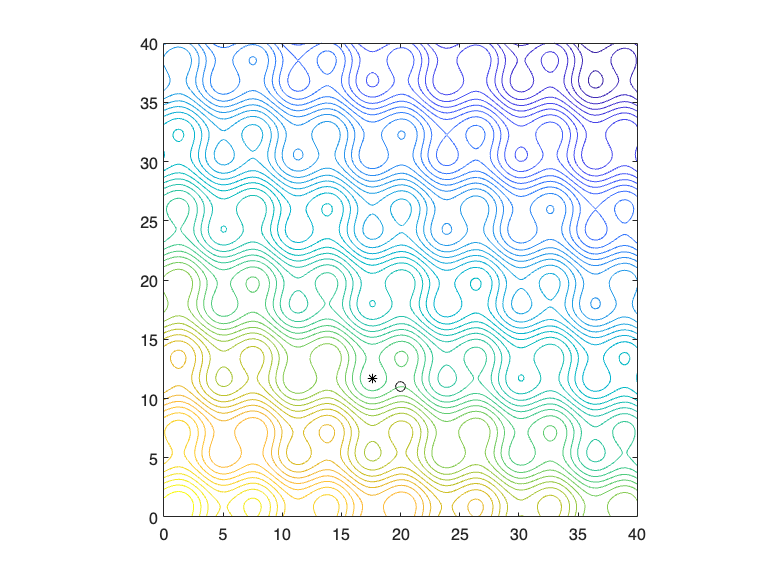

figure;
contour(X,Y,Z,50); axis equal
hold on
plot(xy0(1),xy0(2),'ko') % display starting guess
plot(xy(1),xy(2),'k*') % display optimum

Or indeed, a local optimum that is on the boundary of the domain - (I really hope this isn't dependent on matlab version!). For this one, I ave asked for more return arguments. The output structure shows how many iterations were used and the number of calls funCount to the function funEddieV2.

xy0 = [10,10]'; % for example

[xy,fval,exitflag,output] = fmincon(funEddieV2,xy0,[],[],[],[],[lb;lb],[ub;ub])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xy =    17.6186
   40.0000


fval = -98.2117

exitflag = 1

output = struct with fields:
         iterations: 15
          funcCount: 49
    constrviolation: 0
           stepsize: 1.4999e-07
          algorithm: 'interior-point'
      firstorderopt: 3.6705e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.174273e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


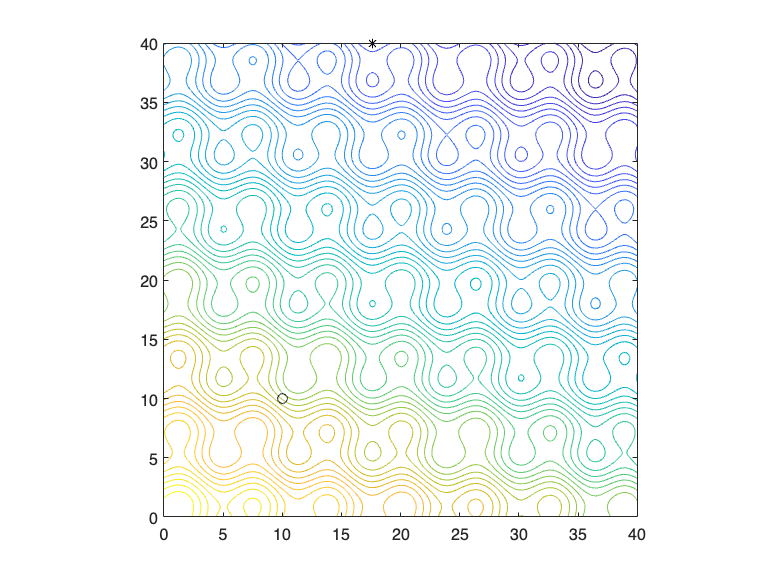

figure;
contour(X,Y,Z,50); axis equal
hold on
plot(xy0(1),xy0(2),'ko') % display starting guess
plot(xy(1),xy(2),'k*') % display optimum

### Summing up...

Further comments: for the standard set-up I've given, you can find the minimum value of the Z matrix - it's -117.0611..., at x=36.4765.. and y=40, ie a boundary minimum, and so the true global optimum on this square must be at least that low (it could be lower if it is achieved between mesh points). None of the above examples find the global optimum. This is the motivation for the final section of the course - weeks 9 and 10 - so-called global optimisation techniques which exploit some kind of parallelism across initial guesses.

As an exercise, try experimenting with lambda, lb, ub, and initial guesses etc. in the above problem set-up.

The suggested analysis is rather easy becasuse $\nabla F=0$ can be solved analytically to find the array of possible local minima. On the boundaries where either x=const. or y=const., the local minima can also be found analytically.